%% ADOM Function
function destriped = ADOM(O, lambda1, lambda2, rho1, rho2, rho3, p, tol, max_iter)
    % ADOM: ADMM-Based Optimization Model for Diagonal Stripe Noise Removal
    % (Modified from original vertical stripe removal)
    % Input: O - observed image (2D matrix)
    %        lambda1, lambda2 - regularization parameters
    %        rho1, rho2, rho3 - penalty parameters
    %        p - threshold for acceleration adjustment
    %        tol - tolerance for convergence
    %        max_iter - maximum iterations
    % Output: destriped - destriped image (O - S)

    if nargin < 9, max_iter = 200; end
    if nargin < 8, tol = 1e-4; end
    if nargin < 7, p = 10; end
    if nargin < 6, rho3 = 1; end
    if nargin < 5, rho2 = 1; end
    if nargin < 4, rho1 = 1; end
    if nargin < 3, lambda2 = 0.1; end
    if nargin < 2, lambda1 = 0.1; end

    [h, w] = size(O);
    delta = 0.1; % As per paper


    % Initialization
    S = zeros(h, w);
    S_prev = S;
    tau1 = zeros(h, w);
    tau2 = zeros(h, w);
    tau3 = zeros(h, w);
    alpha = 1;
    alpha_prev = alpha;
    wn = 1;
    ks = -(w-1):(h-1);
    num_diags = length(ks);
    wg = ones(1, num_diags);
    idxs = cell(1, num_diags);
    for g = 1:num_diags
        k = ks(g);
        rows = max(1, k+1):min(h, k+w);
        cols = rows - k;
        idxs{g} = sub2ind([h, w], rows, cols);
    end
    k = 0;


    % Frequency domain setup for FFT solver
    [Fx, Fy] = meshgrid(0:w-1, 0:h-1);
    F_diag = 1 - exp(-1i * 2 * pi * (Fx / w + Fy / h));
    F_perp = 1 - exp(-1i * 2 * pi * (Fy / h - Fx / w));
    F_diag_conj = conj(F_diag);
    F_perp_conj = conj(F_perp);
    Q = rho1 * (F_diag_conj .* F_diag) + rho2 * (F_perp_conj .* F_perp) + rho3;
    Q(Q==0) = eps; % Avoid division by zero

    while k < max_iter
        k = k + 1;

        % 1. Weight control
        res_curr = O - S;
        res_prev = O - S_prev;
        norm_res_prev = norm(res_prev, 'fro');
        if norm_res_prev == 0
            gamma = 0;
        else
            gamma = norm(res_curr - res_prev, 'fro') / norm_res_prev;
        end
        if alpha - gamma ~= 0
            wn = (alpha_prev + gamma) / (alpha - gamma);
        else
            wn = 1;
        end


        % Update wg
        group_norms = zeros(1, num_diags);
        for g = 1:num_diags
            group_vec = S(idxs{g});
            group_norms(g) = norm(group_vec, 2);
        end
        v = sum(group_norms) / num_diags;
        for g = 1:num_diags
            update_flag = true;
            if g > 1 && abs(group_norms(g) - group_norms(g-1)) >= v
                update_flag = false;
            end
            if g < num_diags && abs(group_norms(g) - group_norms(g+1)) >= v
                update_flag = false;
            end
            if update_flag
                group_vec = S(idxs{g});
                norm_shift = norm(group_vec + gamma, 2);
                if norm_shift > 0
                    wg(g) = 1 / (2 * norm_shift);
                end
            end
        end

        % 2. Evidence-based starting point control
        alpha_prev = alpha;
        if k <= p
            alpha = (1 + sqrt(1 + 4 * alpha_prev^2)) / 2;
        else
            alpha = (1 + sqrt(1 + 2 * alpha_prev^2)) / 2;
        end
        if k <= p
            d = wn;
        else
            d = alpha_prev / alpha;
        end

        % 3. Momentum-based step-size control
        if alpha_prev ~= 0
            S = S + ((alpha - delta) / alpha_prev) * (S - S_prev);
        end
        tau1 = d * tau1;
        tau2 = d * tau2;
        tau3 = d * tau3;


        % 4. ADMM-based subproblem solving
        % Compute gradients (assuming periodic boundaries)
        grad_diag_S = S - circshift(S, [1, 1]); % \nabla_diag S
        grad_perp_S = S - circshift(S, [1, -1]); % \nabla_perp S
        grad_perp_O = O - circshift(O, [1, -1]);

        % Subproblem A
        temp = grad_diag_S + tau1 / rho1;
        A = sign(temp) .* max(abs(temp) - 1 / rho1, 0);

        % Subproblem B
        temp = grad_perp_O - grad_perp_S + tau2 / rho2;
        B = sign(temp) .* max(abs(temp) - (wn * lambda1 / rho2), 0);

        % Subproblem C
        eta = S + tau3 / rho3;
        C = zeros(h, w);
        for g = 1:num_diags
            eta_group = eta(idxs{g});
            norm_eta = norm(eta_group, 2);
            thresh = wg(g) * lambda2 / rho3;
            if norm_eta > thresh
                c_group = eta_group * (norm_eta - thresh) / norm_eta;
                C(idxs{g}) = c_group;
            end
        end

        % Subproblem S
        rhs1 = A - tau1 / rho1;
        rhs2 = grad_perp_O - B + tau2 / rho2;
        rhs3 = C - tau3 / rho3;
        % FFT
        P = rho1 * F_diag_conj .* fft2(rhs1) + rho2 * F_perp_conj .* fft2(rhs2) + rho3 * fft2(rhs3);
        S_new = real(ifft2(P ./ Q));

        % 5. Update Lagrange multipliers
        grad_diag_Snew = S_new - circshift(S_new, [1, 1]);
        grad_perp_Snew = S_new - circshift(S_new, [1, -1]);
        tau1 = tau1 + rho1 * (grad_diag_Snew - A);
        tau2 = tau2 + rho2 * (grad_perp_O - grad_perp_Snew - B);
        tau3 = tau3 + rho3 * (S_new - C);

        % Update S_prev
        S_prev = S;
        S = S_new;

        % Convergence check
        res_curr = O - S;
        res_prev = O - S_prev;
        norm_res_prev = norm(res_prev, 'fro');
        if norm_res_prev > 0 && norm(res_curr - res_prev, 'fro') / norm_res_prev <= tol
            break;
        end
    end

    destriped = O - S;
end


%% Example Usage
% Load a test image (assuming you have a striped image; here we add synthetic stripes to a grayscale image)

% Load example image (replace with your image path)
img = imread("C:\Users\Mahallakshmi\OneDrive\Documents\S3_projects\Mfc_S3\Image.jpg"); % Assuming the uploaded image is saved as this
if size(img,3) > 1
    img = rgb2gray(img);
end
O = im2double(img);
3

ans = 3

% Add synthetic diagonal stripes (e.g., non-periodical)
stripe_ratio = 0.4; % 40%
noise_intensity = 0.5; % Between -0.5 and 0.5
stripes = zeros(size(O));
[h, w] = size(O);
ks = -(w-1):(h-1);
num_diags = length(ks);
num_stripes = round(stripe_ratio * num_diags);
diag_indices = randperm(num_diags, num_stripes);
for gg = diag_indices
    g = gg;
    k = ks(g);
    rows = max(1, k+1):min(h, k+w);
    cols = rows - k;
    idx = sub2ind([h, w], rows, cols);
    constant = (rand() * 2 - 1) * noise_intensity;
    stripes(idx) = constant;
end
O_striped = O + stripes;
O_striped = max(0, min(1, O_striped)); % Clip to [0,1]


% Parameters (tune as needed)
lambda1 = 0.05;
lambda2 = 0.1;
rho1 = 1;
rho2 = 1;
rho3 = 1;
p = 10;
tol = 1e-4;
max_iter = 200;

% Run ADOM
destriped = ADOM(O_striped, lambda1, lambda2, rho1, rho2, rho3, p, tol, max_iter);


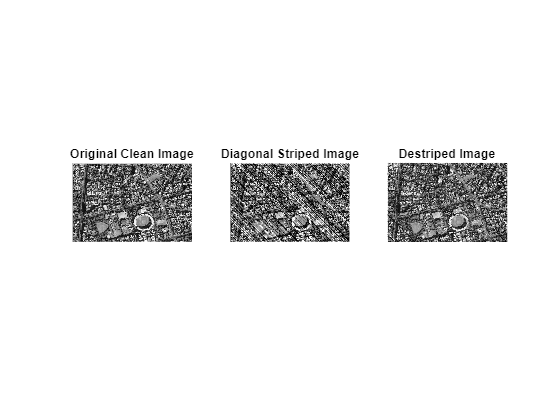

%% Display Results
figure;
subplot(1,3,1); imshow(O); title('Original Clean Image');
subplot(1,3,2); imshow(O_striped); title('Diagonal Striped Image');
subplot(1,3,3); imshow(destriped); title('Destriped Image');